# Ejercicio Nº6

clear;clc;

## Valores de los componentes

R1=1;
R2=1;
L1=2;
C1=1;
C2=1;

w=1;

## Condiciones iniciales

v01=0.5;
v02=0.5;
i01=0.5;

## Valores de tiempo y paso

ti=0;
tf=10;
h=0.001;

## Matrices de forma generalizadas

M=[C1 0 0;0 C2 0;0 0 L1]

M =      1     0     0
     0     1     0
     0     0     2


N=[1/R1 0 1;0 1/R2 -1;-1 1 0]

N =      1     0     1
     0     1    -1
    -1     1     0


Xant=[v01;v02;i01]

Xant =     0.5000
    0.5000
    0.5000


solu=[];

## Método Backward Euler

it=1;
for i= ti:h:tf
    %Fuente variable
    E(it,1)=awgn(0.5*sin(w*i),30);

    %Se calcula el valor de la matriz u para cada punto 
    B=[E(it,1)/R1;0;0];
    
    X=((((1/h).*M)+N)\B) + ((((1/h).*M)+N)\((1/h).*M)*Xant);
    
    solu=[solu X];
    Xant=X;
    it=it+1;
end

solu=solu';

## Gráfico

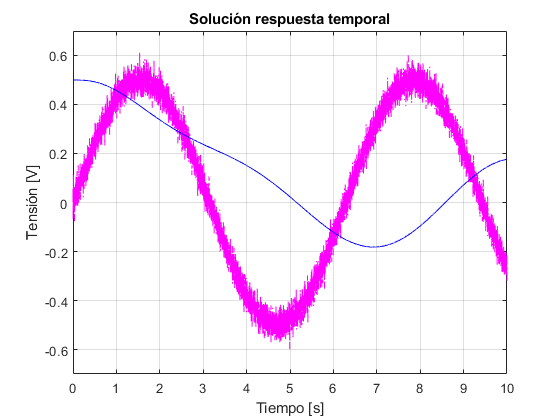

t=ti:h:tf;
plot(t,E,'-.m',t,solu(:,2),'-b')
title('Solución respuesta temporal');
xlabel('Tiempo [s]');
ylabel('Tensión [V]');
ylim([-0.7,0.7])
grid